clear;clc

% Parámetros del sistema

% Ks = 1.61;         % Rigidez del resorte [N/m]
% Jh = 0.0021;       % Inercia del eje del motor [kg*m^2]
% m = 0.403;         % Masa del brazo [kg]
% g = -9.81;         % Aceleración de la gravedad [m/s^2]
% h = 0.06;          % Altura del centro de masa [m]
% Km = 0.00767;      % Constante del motor [N·rad/s]
% Kg = 70;           % Relación de engranaje
% Jl = 0.0059;       % Inercia de la carga [kg*m^2]
% Rm = 2.6;          % Resistencia del motor [Ohm]

% Variables de estado
syms x1 x2 x3 x4 u Ks Jh m g h Km Kg Jl Rm
x=[x1; x2; x3; x4];
%x1 : Ángulo del motor (θ)
%x2 : Deflexión de la articulación (α)
%x3 : Velocidad angular del motor (θ')
%x4 : Velocidad angular de la deflexión (α')
%u  : voltaje de entrada al motor

%% Vector de dinámica f(x)
f1 = x3; 
f2 = x4; 
f3 = ( Ks / Jh )*x2 - ( Km^2 * Kg^2 / (Rm * Jh) )*x3;
f4 = -( Ks/Jh + Ks/Jl )*x2 + ( m * g * h / Jl )*sin( x1 + x2 ) + ( Km^2 * Kg^2 / (Rm * Jh) )*x3;

f = [f1; f2; f3; f4];

%% Vector de entrada g(x)
gs = [0; 0; ( Km * Kg / (Rm * Jh) ); -( Km * Kg / (Rm * Jh) )];

%% Función de salida h(x)
hs = x1 + x2;

### Difemorfismo y grado relativo

Lfh=gradient(hs,x).'*f

$$Lfh = x_{3}+x_{4}$$

Lgh=gradient(hs,x).'*gs

$$Lgh = 0$$

Lf2h=gradient(Lfh,x).'*f

$$Lf2h = \frac{\mathrm{Ks}\,x_{2}}{\mathrm{Jh}}-x_{2}\,\left(\frac{\mathrm{Ks}}{\mathrm{Jh}}+\frac{\mathrm{Ks}}{\mathrm{Jl}}\right)+\frac{g\,h\,m\,\sin\left(x_{1}+x_{2}\right)}{\mathrm{Jl}}$$

LgLfh=gradient(Lfh,x).'*gs

$$LgLfh = 0$$

Lf3h=gradient(Lf2h,x).'*f

$$Lf3h = \frac{g\,h\,m\,x_{3}\,\cos\left(x_{1}+x_{2}\right)}{\mathrm{Jl}}-x_{4}\,\left(\frac{\mathrm{Ks}}{\mathrm{Jl}}-\frac{g\,h\,m\,\cos\left(x_{1}+x_{2}\right)}{\mathrm{Jl}}\right)$$

LgL2h=gradient(Lf2h,x).'*gs

$$LgL2h = 0$$

Lf4h=gradient(Lf3h,x).'*f

$$Lf4h = \begin{array}{l} \frac{g\,h\,m\,\cos\left(x_{1}+x_{2}\right)\,\left(\frac{\mathrm{Ks}\,x_{2}}{\mathrm{Jh}}-\sigma_{2}\right)}{\mathrm{Jl}}-x_{4}\,\sigma_{1}-\left(\frac{\mathrm{Ks}}{\mathrm{Jl}}-\frac{g\,h\,m\,\cos\left(x_{1}+x_{2}\right)}{\mathrm{Jl}}\right)\,\left(\frac{g\,h\,m\,\sin\left(x_{1}+x_{2}\right)}{\mathrm{Jl}}-x_{2}\,\left(\frac{\mathrm{Ks}}{\mathrm{Jh}}+\frac{\mathrm{Ks}}{\mathrm{Jl}}\right)+\sigma_{2}\right)-x_{3}\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\frac{g\,h\,m\,x_{3}\,\sin\left(x_{1}+x_{2}\right)}{\mathrm{Jl}}+\frac{g\,h\,m\,x_{4}\,\sin\left(x_{1}+x_{2}\right)}{\mathrm{Jl}}\\ \sigma_{2}=\frac{{\mathrm{Kg}}^{2}\,{\mathrm{Km}}^{2}\,x_{3}}{\mathrm{Jh}\,\mathrm{Rm}} \end{array}$$

LgL3h=gradient(Lf3h,x).'*gs

$$LgL3h = \frac{\mathrm{Kg}\,\mathrm{Km}\,\left(\frac{\mathrm{Ks}}{\mathrm{Jl}}-\frac{g\,h\,m\,\cos\left(x_{1}+x_{2}\right)}{\mathrm{Jl}}\right)}{\mathrm{Jh}\,\mathrm{Rm}}+\frac{\mathrm{Kg}\,\mathrm{Km}\,g\,h\,m\,\cos\left(x_{1}+x_{2}\right)}{\mathrm{Jh}\,\mathrm{Jl}\,\mathrm{Rm}}$$


z1=hs

$$z1 = x_{1}+x_{2}$$

z2=Lfh

$$z2 = x_{3}+x_{4}$$

z3=Lf2h

$$z3 = \frac{\mathrm{Ks}\,x_{2}}{\mathrm{Jh}}-x_{2}\,\left(\frac{\mathrm{Ks}}{\mathrm{Jh}}+\frac{\mathrm{Ks}}{\mathrm{Jl}}\right)+\frac{g\,h\,m\,\sin\left(x_{1}+x_{2}\right)}{\mathrm{Jl}}$$

z4=Lf3h

$$z4 = \frac{g\,h\,m\,x_{3}\,\cos\left(x_{1}+x_{2}\right)}{\mathrm{Jl}}-x_{4}\,\left(\frac{\mathrm{Ks}}{\mathrm{Jl}}-\frac{g\,h\,m\,\cos\left(x_{1}+x_{2}\right)}{\mathrm{Jl}}\right)$$

v=Lf4h+LgL3h*u;
v=simplify(v)

$$v = -\frac{\mathrm{Jl}\,{\mathrm{Kg}}^{2}\,{\mathrm{Km}}^{2}\,\mathrm{Ks}\,x_{3}-\mathrm{Jl}\,{\mathrm{Ks}}^{2}\,\mathrm{Rm}\,x_{2}-\mathrm{Jl}\,\mathrm{Kg}\,\mathrm{Km}\,\mathrm{Ks}\,u-\mathrm{Jh}\,{\mathrm{Ks}}^{2}\,\mathrm{Rm}\,x_{2}-\frac{\mathrm{Jh}\,\mathrm{Rm}\,g^{2}\,h^{2}\,m^{2}\,\sin\left(2\,x_{1}+2\,x_{2}\right)}{2}+\mathrm{Jh}\,\mathrm{Ks}\,\mathrm{Rm}\,g\,h\,m\,\sin\left(x_{1}+x_{2}\right)+\mathrm{Jh}\,\mathrm{Jl}\,\mathrm{Rm}\,g\,h\,m\,{x_{3}}^{2}\,\sin\left(x_{1}+x_{2}\right)+\mathrm{Jh}\,\mathrm{Jl}\,\mathrm{Rm}\,g\,h\,m\,{x_{4}}^{2}\,\sin\left(x_{1}+x_{2}\right)+\mathrm{Jh}\,\mathrm{Ks}\,\mathrm{Rm}\,g\,h\,m\,x_{2}\,\cos\left(x_{1}+x_{2}\right)+2\,\mathrm{Jh}\,\mathrm{Jl}\,\mathrm{Rm}\,g\,h\,m\,x_{3}\,x_{4}\,\sin\left(x_{1}+x_{2}\right)}{\mathrm{Jh}\,{\mathrm{Jl}}^{2}\,\mathrm{Rm}}$$

### **Control linealizador**


$$u=\frac{1}{L_gL_f^{3}h(x)}\left[-L_f^{4}h(x)+v\right]$$


clear v
syms v;
u=1/LgL3h*(v-Lf4h);
u=simplify(u)

$$u = \frac{\mathrm{Jh}\,{\mathrm{Jl}}^{2}\,\mathrm{Rm}\,v-\mathrm{Jh}\,{\mathrm{Ks}}^{2}\,\mathrm{Rm}\,x_{2}-\mathrm{Jl}\,{\mathrm{Ks}}^{2}\,\mathrm{Rm}\,x_{2}+\mathrm{Jl}\,{\mathrm{Kg}}^{2}\,{\mathrm{Km}}^{2}\,\mathrm{Ks}\,x_{3}-\frac{\mathrm{Jh}\,\mathrm{Rm}\,g^{2}\,h^{2}\,m^{2}\,\sin\left(2\,x_{1}+2\,x_{2}\right)}{2}+\mathrm{Jh}\,\mathrm{Ks}\,\mathrm{Rm}\,g\,h\,m\,\sin\left(x_{1}+x_{2}\right)+\mathrm{Jh}\,\mathrm{Jl}\,\mathrm{Rm}\,g\,h\,m\,{x_{3}}^{2}\,\sin\left(x_{1}+x_{2}\right)+\mathrm{Jh}\,\mathrm{Jl}\,\mathrm{Rm}\,g\,h\,m\,{x_{4}}^{2}\,\sin\left(x_{1}+x_{2}\right)+\mathrm{Jh}\,\mathrm{Ks}\,\mathrm{Rm}\,g\,h\,m\,x_{2}\,\cos\left(x_{1}+x_{2}\right)+2\,\mathrm{Jh}\,\mathrm{Jl}\,\mathrm{Rm}\,g\,h\,m\,x_{3}\,x_{4}\,\sin\left(x_{1}+x_{2}\right)}{\mathrm{Jl}\,\mathrm{Kg}\,\mathrm{Km}\,\mathrm{Ks}}$$

Az=[0 1 0 0; 0 0 1 0; 0 0 0 1; 0 0 0 0];
Bz=[0; 0; 0; 1];
Cz=[1 0 0 0];
Control=ctrb(Az,Bz);
rank(Control)

ans = 4

tsdes = 2;
zeta=0.8;
wn=4/(zeta*tsdes);
polos1=roots([1 2*zeta*wn wn^2]);
 P=[polos1' 10*polos1'];
%P=[-4 -4 -10 -20];
Kej4 = acker(Az,Bz,P)

Kej4 = 1.0e+03 *

    3.9063    2.7500    0.7913    0.0440



%con integrador
Aa=[Az zeros(4,1);...
    Cz zeros(1,1)];
Ba=[Bz;zeros(1,1)];


P=[polos1' 5*polos1' 10*real(polos1(1))];
%P=[-1 -1 -50];
Kej4b = acker(Aa,Ba,P)

Kej4b = 1.0e+04 *

    1.5977    0.5600    0.0722    0.0044    1.9531


#### Variables necesarias para el modelo simulink

pert=0.08;
sim("Flex_Joint.slx")

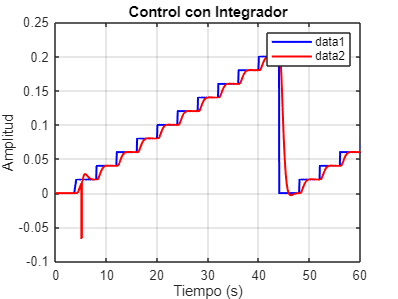


% Primer gráfico
figure;
plot(y1.time, y1.signals(1).values(:,1), 'b', 'LineWidth', 1.5);hold on;
plot(y1.time, y1.signals(1).values(:,2), 'r', 'LineWidth', 1.5)
title('Control con Integrador', 'Interpreter', 'tex');
xlabel('Tiempo (s)', 'Interpreter', 'tex');
ylabel('Amplitud', 'Interpreter', 'tex');
legend
grid on;

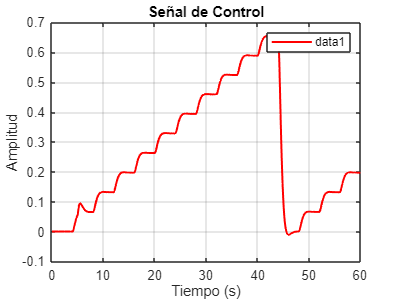


% Segundo gráfico
figure;
plot(y1.time, y1.signals(2).values, 'r', 'LineWidth', 1.5);
title('Señal de Control', 'Interpreter', 'tex');
xlabel('Tiempo (s)', 'Interpreter', 'tex');
ylabel('Amplitud', 'Interpreter', 'tex');
legend
grid on;

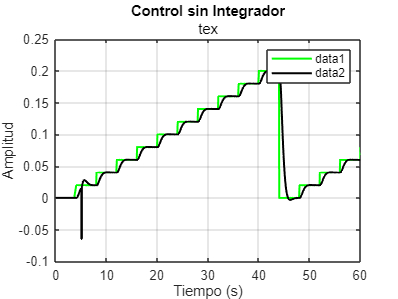


% Tercer gráfico
figure;
plot(y2.time, y2.signals(1).values(:,1), 'g', 'LineWidth', 1.5);hold on ;
plot(y2.time, y2.signals(1).values(:,2), 'black', 'LineWidth', 1.5);
title('Control sin Integrador', 'tex');
xlabel('Tiempo (s)', 'Interpreter', 'tex');
ylabel('Amplitud', 'Interpreter', 'tex');
legend
grid on;

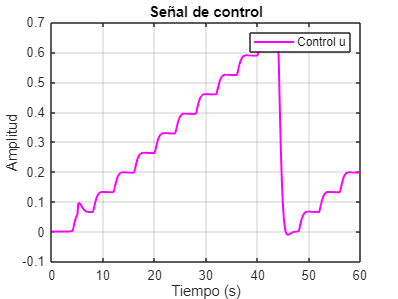


% Cuarto gráfico
figure;
plot(y2.time, y2.signals(2).values, 'm', 'LineWidth', 1.5);
title('Señal de control', 'Interpreter', 'tex');
xlabel('Tiempo (s)', 'Interpreter', 'tex');
ylabel('Amplitud', 'Interpreter', 'tex');
legend('Señal 2', 'Interpreter', 'tex');
grid on;

legend(["Control u"], "Interpreter", "tex")

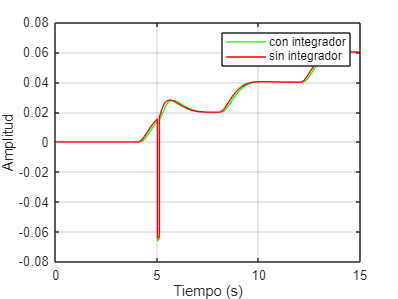


figure;
plot(y1.time, y1.signals(1).values(:,2), 'g', 'LineWidth', 1);hold on ;
plot(y2.time, y2.signals(1).values(:,2), 'r', 'LineWidth', 0.5);

xlabel('Tiempo (s)', 'Interpreter', 'tex');
ylabel('Amplitud', 'Interpreter', 'tex');
legend
xlim([0 15])
grid on;

legend(["con integrador", "sin integrador"])

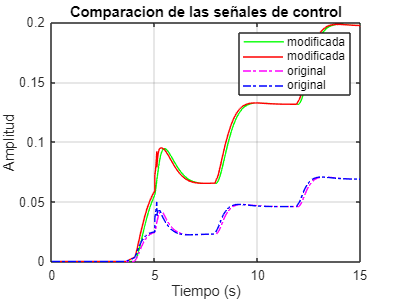

figure;
plot(y1.time, y1.signals(2).values, 'g', 'LineWidth', 1);hold on ;
plot(y2.time, y2.signals(2).values, 'r', 'LineWidth', 0.5);
plot(ScopeData4.time, ScopeData4.signals(2).values, 'm -.', 'LineWidth', 0.5);
plot(ScopeData1.time, ScopeData1.signals(2).values, 'b -.', 'LineWidth', 0.5);
xlabel('Tiempo (s)', 'Interpreter', 'tex');
ylabel('Amplitud', 'Interpreter', 'tex');
title("Comparacion de las señales de control")
legend
xlim([0 15])
grid on;

xlim([0.0 15.0])
legend(["modificada", "modificada", "original", "original"])